# Running Python Code With MATLAB

There are many programming languages in the world and they all have different features. You may have occasions where you want to reuse existing code, call on functionality from another language, or collaborate with someone who prefers to work in a different language than you. It is quite possible to use multiple programming languages together, although in some cases the interface may be awkward if the underlying structures are different. This script introduces a Live Task that can be used as a graphical user interface to run Python code from MATLAB.

This script is intended to be run one section at a time, in order. If you choose to skip around, you may encounter errors.

## Getting ready

### Step 1: Check your MATLAB version 

Including user-authored Live Tasks is only supported starting in R2022a. What version are you running?

releaseInfo = matlabRelease;
str = "This is release " + releaseInfo.Release + ",";
if isMATLABReleaseOlderThan("R2022a")
    disp(str + " so it will not run this example.")
else
    disp(str + " so you can proceed with this script.")
end

This is release R2026b, so you can proceed with this script.


### Step 2: Check your Python version

You must have Python installed, and it must be a [supported version of Python](https://www.mathworks.com/content/dam/mathworks/mathworks-dot-com/support/sysreq/files/python-compatibility.pdf) for your MATLAB version. For R2022a, you need to use 2.7, 3.8, or 3.9. What version are you using?

If you do not have a supported version of Python installed, follow the instructions in the [documentation to install and select](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html) a supported version. If you have a supported version of Python installed, but it is not on your MATLAB path, you will need to add it using `addpath`

Check which Python environment(s) MATLAB can see:

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.14"
       Executable: "C:\Users\lsammon\AppData\Local\Python\pythoncore-3.14-64\python.exe"
          Library: "C:\Users\lsammon\AppData\Local\Python\pythoncore-3.14-64\python314.dll"
             Home: "C:\Users\lsammon\AppData\Local\Python\pythoncore-3.14-64"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "7072"
      ProcessName: "MATLABPyHost"


% you can specify different parameters for your Python environment. Visit
% the pyenv documentation for more information.

pstudent=py.tuple({'Robert',19,'Biology'})

pstudent =   Python tuple with values:

    ('Robert', 19.0, 'Biology')

    Use string, double or cell function to convert to a MATLAB array.


pstudent{1}

ans =   Python str with no properties.

    Robert


z = complex(1,2);
py.cmath.polar(z)

ans =   Python tuple with values:

    (2.23606797749979, 1.1071487177940904)

    Use string, double or cell function to convert to a MATLAB array.


### Step 3: Download and install the MATLAB Live Task for Python

Navigate to the Add-Ons section in the Home Tab on the toolstrip.

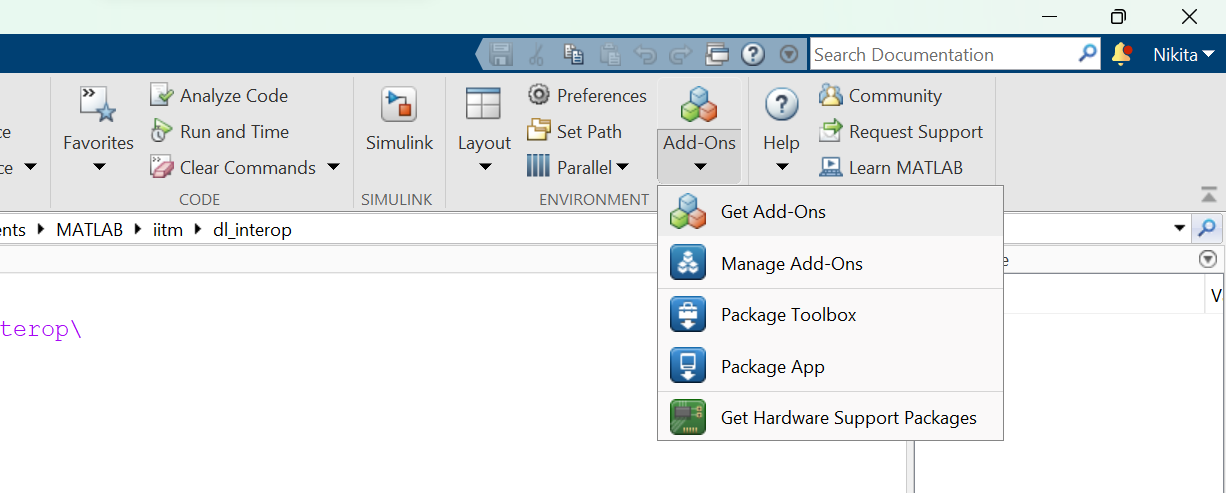

Search for **MATLAB Live Task for Python **

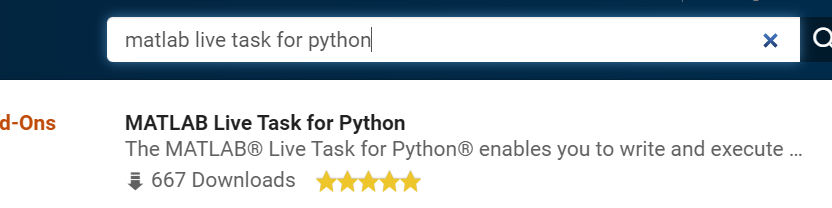

Open the package, and install it. 

You can find the Live Task called '**Run Python code**' in the Tasks section on the Insert Tab of the livescript. 

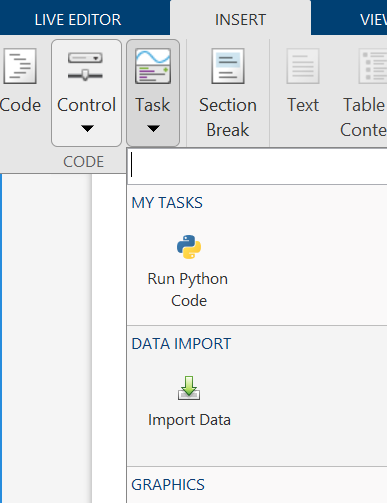

### Run Python statements

Clear your workspace, for ease of navigation, and set up variables to use as input.

clear
dollars = "35.12";
percent = "5.2";

% Python code input
pycode = [...
"# Sample Python code ",...
"amount = float(dollars.lstrip(""$""))",...
"rate = float(percent.rstrip(""%""))/100",...
"tax = amount*rate",...
"print(""The tax due is: "")",...
"print(round(tax,2))"...
];

try
    [amount, rate, tax2] = pyrun(pycode, ...
         [ "amount" "rate" "tax" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

Python Error: NameError: name 'dollars' is not defined


% Clear temporary variables from workspace and from Python
clear pycode;


Now check the variable in MATLAB, after processing it using a Python script/lines of code.  

% check the tax
tax

tax = 1.8262

#### Sample code to run

#### Python Live Task to run python files

EMI calculator

principal = 225000;
interestRate = 0.17;

% Python code input
pycode3 = [...
"C:\Users\lsammon\OneDrive - MathWorks\Documents\MATLAB\4_Seminars\USGS Denver 2026\MATLAB Interoperability\Demo MATLAB and Python\python_in_matlab_livetask\functionEMICalculator.py "...
];

[EMI] = pyrunfile(pycode3, ...
         [ "EMI" ], "principal", principal, "interestRate", interestRate)

EMI = 2.0234e+04

% Clear temporary variables from workspace and from Python
clear pycode3;

whos EMI

  Name      Size            Bytes  Class     Attributes

  EMI       1x1                 8  double              



Check the value 

EMI

EMI = 2.0234e+04

You can also use code to call .py files 

EMI_code = pyrunfile('functionEMICalculator.py', 'EMI', ...
    principal = principal, interestRate = interestRate);
EMI_code

EMI_code = 2.0234e+04